clc
% 获取control_logger数据表格
ulogOBJ = ulogreader("HILSimData\log_1_2021-6-30-08-03-14.ulg");
msg = readTopicMsgs(ulogOBJ);

## 优化指标

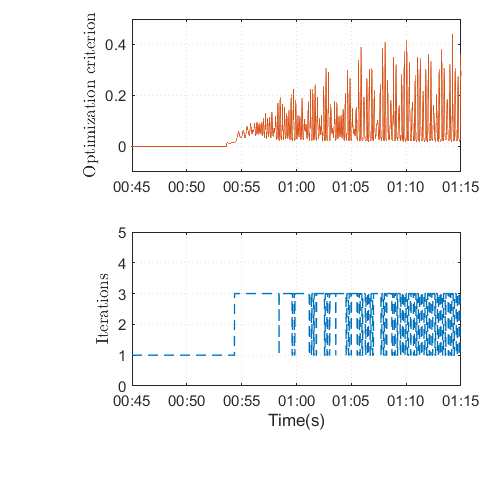

control_logger = msg.TopicMessages{6};
% 获取log数据和时间序列
log_time = control_logger.timestamp;
fval = control_logger.fval;
iter = control_logger.iter;
channel_optimization = control_logger.channel_opti;
channel = control_logger.channel;
jmin = control_logger.jmin;

figure(1)
% subplot(3,1,1)
% plot(log_time,jmin,'--','Color','#D95319','LineWidth',1)
% hold on
% plot(log_time,fval,"Color",'#0072BD')
% ylim([-300 0])
% legend('Optimization Objective Reference','Optimization Objective','box','off','location','southwest');
tstop = 3800;
subplot(2,1,1)
plot(log_time(1:tstop),fval(1:tstop) - jmin(1:tstop),'Color','#D95319','LineWidth',1)
ylim([-0.1 0.5])
xlim([duration(0,0,45),duration(0,1,15)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel('Optimization criterion','Interpreter',"latex")

subplot(2,1,2)
plot(log_time(1:tstop),iter(1:tstop),'--',"Color",'#0072BD','LineWidth',1)
xlabel('Time(s)')
ylim([0 5])
xlim([duration(0,0,45),duration(0,1,15)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel('Iterations','Interpreter',"latex")

## 电机拉力数据

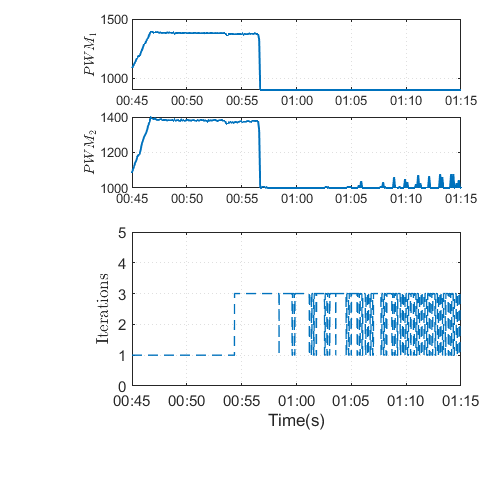

actuator_outputs = msg.TopicMessages{2};
actuator_outputs_time = actuator_outputs.timestamp;
output = actuator_outputs.output;
% 替换冲突数据
for j = 1:4
    for i = 2:1461
        if output(i,j)==1500
            output(i,j) = output(i-1,j);
        end
    end
end
% 画图
figure(2)
subplot(4,1,1)
tstop = 350;
plot(actuator_outputs_time(1:tstop),output(1:tstop,1),"Color",'#0072BD','LineWidth',1.5);
% ylim([0 5]);
xlim([duration(0,0,45),duration(0,1,15)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel('$PWM_{1}$','Interpreter',"latex");

subplot(4,1,2)
plot(actuator_outputs_time(1:tstop),output(1:tstop,2),"Color",'#0072BD','LineWidth',1.5);
% ylim([0 5]);
xlim([duration(0,0,45),duration(0,1,15)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel('$PWM_{2}$','Interpreter',"latex");

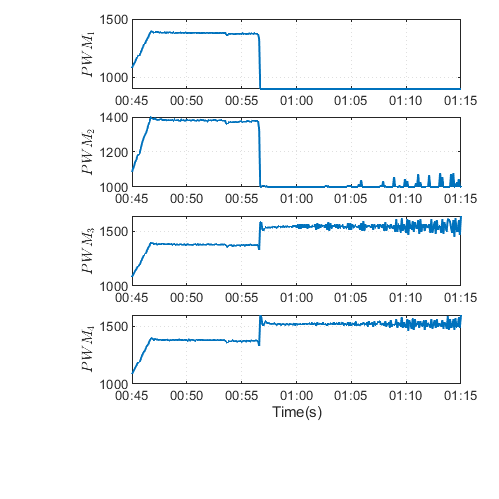

subplot(4,1,3);
plot(actuator_outputs_time(1:tstop),output(1:tstop,3),"Color",'#0072BD','LineWidth',1.5);
% ylim([0 5]);
xlim([duration(0,0,45),duration(0,1,15)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel('$PWM_{3}$','Interpreter',"latex");

subplot(4,1,4);
plot(actuator_outputs_time(1:tstop),output(1:tstop,4),"Color",'#0072BD','LineWidth',1.5);
% ylim([0 5]);
xlim([duration(0,0,45),duration(0,1,15)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel('$PWM_{4}$','Interpreter',"latex");
xlabel('Time(s)');

## 获取角速率数据

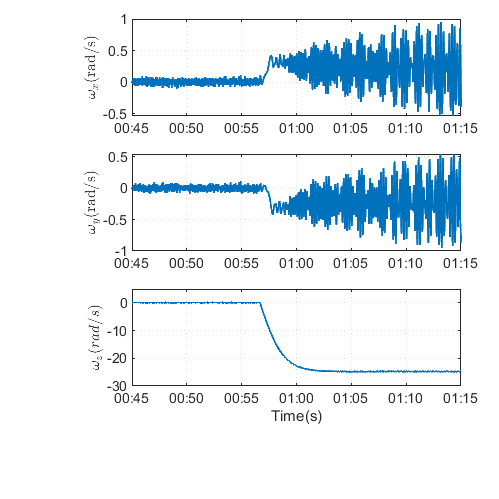

sensor_combine = msg.TopicMessages{24};
gyro = sensor_combine.gyro_rad;
% sensor_time1 = 0:0.005:207.445;
sensor_time = sensor_combine.timestamp;
figure(3)
tstop = 10000;
subplot(3,1,1)
plot(sensor_time(1:tstop), gyro(1:tstop,1),"Color",'#0072BD','LineWidth',1.5)
% ylim([0 5])
xlim([duration(0,0,45),duration(0,1,15)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel("$\omega_x$(rad/s)",'Interpreter',"latex")

subplot(3,1,2)
plot(sensor_time(1:tstop), gyro(1:tstop,2),"Color",'#0072BD','LineWidth',1.5)
% ylim([0 5])
xlim([duration(0,0,45),duration(0,1,15)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel("$\omega_y$(rad/s)",'Interpreter',"latex")

subplot(3,1,3)
plot(sensor_time(1:tstop), gyro(1:tstop,3),"Color",'#0072BD','LineWidth',1.5)
ylim([-30, 5])
xlim([duration(0,0,45),duration(0,1,15)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel("$\omega_z(rad/s)$",'Interpreter',"latex")
xlabel("Time(s)")